# normalization models, feedback and feed forward

## HEEGER 1992: FEEDBACK NORMALIZATION

## HEEGER 1992: (1) set up

% The point here is this: the unnormalized outputs cannot be represented by mechanisms with limited dynamic rnage (e.g. neurons). 
% The solution is to use a feedback network to do the normalization. Then the unnormalized outpus need not be explicitly represented 
% as cell output firing rates. 

% This is implemented by a low-passed feedbacj signal, to avoid any instability in the system:

t = 0.001 : 0.001 : 1; t_lth = length(t);

R_t = zeros(1, t_lth); % output to the system
B_t = zeros(1, t_lth); % feedback to the system

I_t = zeros(1, length(t)); % stimulus
I_t(t >0.05 & t < 0.2) = 1; 

% model constants:
delta = 2;    % time delay, number of period, each period lasts 0.001 second
alpha = 0.01; % weight between current output and the past feedback signal
R_max = 1;    % miximum output response
sigma = 0.1;  % normalization constant


## HEEGER 1992: (2) compute model prediction

% IMPLEMENT THE MODEL: the input is multiplied by the feedback signal
for it = 2 : t_lth
    B_t(it) = alpha * R_t(it) + (1- alpha) * B_t(max(it - delta, 1)); % this is where the exponential decay comes from
    R_t(it + delta) = I_t(it)./sigma * (R_max - B_t(it));
end

## HEEGER 1992: (3) visualization

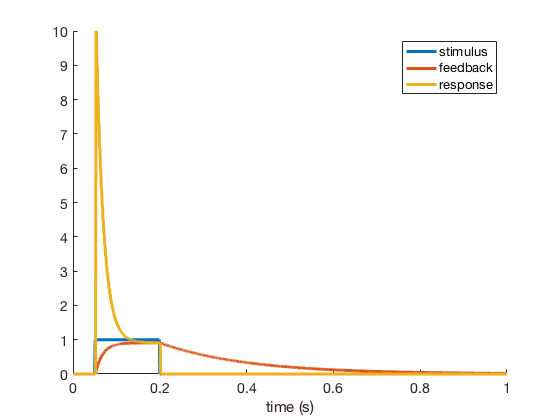

figure (1), clf
plot(t, I_t, t, B_t(1 : t_lth), t, R_t(1 : t_lth), 'linewidth', 3), box off
legend('stimulus', 'feedback', 'response'), set(gca, 'fontsize', 14), xlabel('time (s)')